# Naive Bayes

% Ler o ficheiro CSV
data = readtable('dataset1.csv');
% Exibir os nomes das colunas
%disp(data.Properties.VariableNames);

% Dividir a coluna única em duas: Frases e Categoria
splitData = split(data.Text, ' : ');

frases = splitData(:, 1); % Coluna com as frases
%categorias = splitData(:, 2); % Coluna com as categoria


categorias = cell(height(data), 1);
for ctg = 1 : height(data)
    categorias{ctg} = data.Category{ctg};
end
%disp(categorias);

%rrmover linhas duplicadas
%(fazer isto)


% ------------------------------
%dividir o dataset em treino e teste (60% treino, 40% teste)

% Total de linhas
numRows = size(data, 1);

% Gerar índices aleatórios
randIndices = randperm(numRows);

% Determinar limites para treino e teste
trainLimit = round(0.6 * numRows);

% Conjuntos de treino e teste
trainIndices = randIndices(1:trainLimit);
testIndices = randIndices(trainLimit + 1:end);

% Separar frases e categorias para treino
trainFrases = frases(trainIndices);
trainCategorias = categorias(trainIndices);

% Separar frases e categorias para teste
testFrases = frases(testIndices);
testCategorias = categorias(testIndices);

% Exibir resultados para validação
%disp('Conjunto de treino (frases):');
%disp(trainFrases);

%disp('Conjunto de treino (categorias):');
%disp(trainCategorias);

%disp('Conjunto de teste (frases):');
%disp(testFrases);

%disp('Conjunto de teste (categorias):');
%disp(testCategorias);
    
%--------------------------------

% Processamento das trainFrases

% Converter as frases para string para facilitar o processamento
trainFrases = string(trainFrases);
trainFrases = lower(trainFrases);
frasestoken = tokenizedDocument(trainFrases);
%customStopWords = [stopWords "there's" "someone"];
%customStopWords = string(customStopWords);

% Remover as stopwords usando removeStopWords
cleanfrasestoken = removeStopWords(frasestoken);
cleanfrases = joinWords(cleanfrasestoken);

trainFrases = string(cleanfrases);
%remover pontos finais das frases
trainFrases = regexprep(trainFrases, '\.$', '');
%remover virgulas das frases
trainFrases = regexprep(trainFrases, ',', '');


%converter texto em minusculas
trainFrases = lower(trainFrases);
disp(trainFrases);

    "elderly woman holding head crying pain "
    "smoke billowing construction site "
    "reports violence mall "
    "someone unconscious breathing public square "
    "heard loud crash next door "
    "small explosion occurred chemical wing university "
    "smoke alarms going off crowded shopping mall "
    "flooding submerged train station up platform level "
    "reports harassment stadium "
    "someone following downtown area "
    "two people fighting aggressively middle busy street "
    "there's aggressive animal loose "
    "notice smoke coming nearby house "
    "someone bitten venomous snake "
    "there's major earthquake causing structural damage "
    "emergency medical attention required ferry terminal "
    "person collapsed suddenly ferry terminal "
    "structural collapse construction site "
    "suspicious vehicle parked front building hours "
    "someone bleeding heavily shopping center "
    "someone knocking windows late night scaring residents "
    "someon



% Processamento das testFrases

% Converter as frases para string para facilitar o processamento
testFrases = string(testFrases);
testFrases = lower(testFrases);
frasestoken = tokenizedDocument(testFrases);
%customStopWords = [stopWords "there's" "someone"];
%customStopWords = string(customStopWords);

% Remover as stopwords usando removeStopWords
cleanfrasestoken = removeStopWords(frasestoken);
cleanfrases = joinWords(cleanfrasestoken);

testFrases = string(cleanfrases);
%remover pontos finais das frases
testFrases = regexprep(testFrases, '\.$', '');
%remover virgulas das frases
testFrases = regexprep(testFrases, ',', '');


%converter texto em minusculas
testFrases = lower(testFrases);
disp(testFrases);

    "tourist collapsed near entrance museum "
    "protest blocking main road "
    "witnessed chemical spill highway "
    "suspicious individual following others ferry terminal "
    "dog stuck fence "
    "person fell height public square "
    "hazardous situation developing high-rise building "
    "massive wave hit coastal area  causing severe damage "
    "someone peeking fence backyard "
    "reports violence highway "
    "loud altercation occurring busy market "
    "dangerous chemical spill occurred high-rise building "
    "someone spray-painting graffiti walls public school "
    "leaking tanker causing hazardous conditions highway "
    "large chemical plant exploded "
    "structural collapse restaurant "
    "someone fallen moving sidewalk "
    "there's emergency dam "
    "landslide trapped cars mountain road "
    "river rising dangerously due continuous rain "
    "man collapsed jogging trail "
    "someone broken park "
    "oil tanker spilling fuel river "
    "lo


%------------------------------

%criar o vocabulário único das frases (lista de palavras únicas)
vocabulary = createVocabulary(trainFrases);
%remover strings vazias
vocabulary = vocabulary(vocabulary ~= "")

vocabulary = 994×1 string array
    "abandoned"
    "abdomen"
    "abdominal"
    "ablaze"
    "access"
    "accident"
    "acting"
    "active"
    "affected"
    "affecting"
    "against"
    "aggressive"
    "aggressively"
    "agony"
    "agricultural"
    "air"
    "airplane"
    "airport"
    "alarm"
    "alarms"
    "alert"
    "allergic"
    "alley"
    "alleyway"
    "altercation"
    "ambulance"
    "amusement"
    "angrily"
    "animal"
    "ankle"


%disp('Vocabulário único:');
%disp(vocabulary);

%------------------------------

%criar a matriz Bag-of-Words (número de ocorrências)
numFrases = length(trainFrases);
numWords = length(vocabulary);

%inicializar a matriz com zeros
matriz_ocorrencias = zeros(numFrases, numWords);

%preencher a matriz Bag-of-Words
for ctg = 1:numFrases
    %dividir a frase atual em palavras
    words = split(trainFrases{ctg});
    for j = 1:numWords
        %contar as ocorrências da palavra atual na frase atual
        matriz_ocorrencias(ctg, j) = sum(strcmp(words, vocabulary{j}));
    end
end

%exibir a matriz de ocorrências - linhas = frases || colunas = palavras
%ou seja, esta é a primeira linha da matriz
%1     0     0     0     0     0
%significa que na primeria frase aparece uma vez a primeria palavra da Bag-of-Words
disp('Matriz Ocorrências:');

Matriz Ocorrências:


disp(matriz_ocorrencias);

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

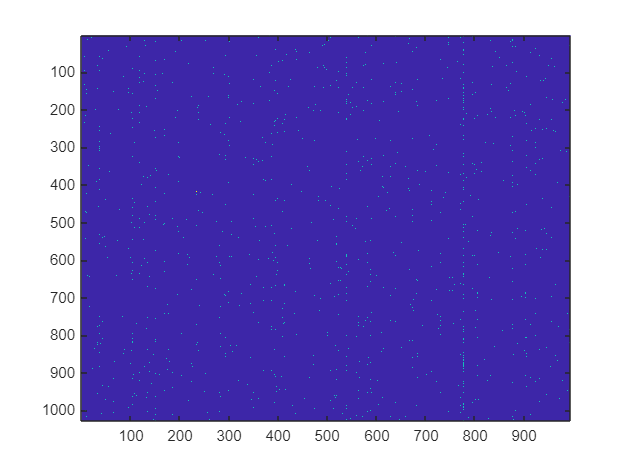

imagesc(matriz_ocorrencias)

% ------------------------------

% Criar um vetor com a frase correspondente a cada linha da matriz
% O vetor será simplesmente as frases, já que cada linha da matriz ocorrências
% corresponde a uma frase única.
fraseCorrespondente = trainFrases;
disp(trainFrases);

    "elderly woman holding head crying pain "
    "smoke billowing construction site "
    "reports violence mall "
    "someone unconscious breathing public square "
    "heard loud crash next door "
    "small explosion occurred chemical wing university "
    "smoke alarms going off crowded shopping mall "
    "flooding submerged train station up platform level "
    "reports harassment stadium "
    "someone following downtown area "
    "two people fighting aggressively middle busy street "
    "there's aggressive animal loose "
    "notice smoke coming nearby house "
    "someone bitten venomous snake "
    "there's major earthquake causing structural damage "
    "emergency medical attention required ferry terminal "
    "person collapsed suddenly ferry terminal "
    "structural collapse construction site "
    "suspicious vehicle parked front building hours "
    "someone bleeding heavily shopping center "
    "someone knocking windows late night scaring residents "
    "someon


% ------------------------------

% numero de casos favoraveis/ numero de casos possiveis 
% P(I) - prob de calhar I a dividir por todos
% P(B) - ...
% P(P) - ...

% Depois tenho que fazer a % P("palavra_à_escolha"|I) = (categoria palavra_à_escolha na classe I) / (numero de palavras na classe I)
% fazer isto para os três casos, I, P, B


%calcular P(I), P(B) e P(P)

%categorias
categorias_unicas = ['I', 'B', 'P'];

%probs das categorias
probabilidades_categoria = zeros(length(categorias_unicas), 1);

%contar ocorrências de cada categoria e calcular a probabilidade
for ctg = 1:length(categorias_unicas)
    categoria_count = sum(strcmp(trainCategorias, categorias_unicas(ctg))); %retorna 1 se forem iguais e soma todos os 1
    probabilidades_categoria(ctg) = categoria_count / length(trainCategorias); %casos favoraveis a dividir por casos totais
end


%exibir as probabilidades das categorias
disp('Probabilidades das categorias:');

Probabilidades das categorias:


for ctg = 1:length(categorias_unicas)
    fprintf('P(%s) = %.3f\n', categorias_unicas(ctg), probabilidades_categoria(ctg));
end

P(I) = 0.296
P(B) = 0.388
P(P) = 0.316


%calcular probs condicionadas

%criar matriz prob cond para cada palavra dada uma categoria
num_categorias = length(categorias_unicas);
prob_cond = zeros(num_categorias, numWords); %aqui linhas = categorias e colunas = palavras

%suavização de laplace (para evitar prob zero)
suavizacao_laplace = 1;

%calcular P(palavra | categoria)
for c = 1:num_categorias
    %vou filtrar frases que pertencem à categoria atual
    categoria_atual = categorias_unicas(c);
    indices_categorias = strcmp(trainCategorias, categoria_atual); %retorna 1 se for a mesma categoria
    frases_categoria = trainFrases(indices_categorias);

    %contar ocorrências de cada palavra nas frases da categoria
    total_palavras_categoria = 0;
    palavras_por_categoria = zeros(1, numWords); %counter para cada palavra

    for f = 1:length(frases_categoria)
        %dividir frase em palavras
        palavras = split(frases_categoria{f});

        %atualizar contadores
        total_palavras_categoria = total_palavras_categoria + length(palavras);

        for p = 1:numWords
            palavras_por_categoria(p) = palavras_por_categoria(p) + sum(strcmp(palavras, vocabulary{p}));
        end
    end

    %calcular probs cond
    prob_cond(c, :) = (palavras_por_categoria + suavizacao_laplace) ./ (total_palavras_categoria + numWords * suavizacao_laplace);
end


for ctg = 1:num_categorias
    fprintf('Probabilidades condicionais para a categoria %s:\n', categorias_unicas(ctg));
    for j = 1:numWords
        fprintf('P(%s | %s) = %.4f\n', vocabulary{j}, categorias_unicas(ctg), prob_cond(ctg, j));
    end
    fprintf('\n');
end

Probabilidades condicionais para a categoria I:


P(abandoned | I) = 0.0004
P(abdomen | I) = 0.0007
P(abdominal | I) = 0.0018
P(ablaze | I) = 0.0004
P(access | I) = 0.0004
P(accident | I) = 0.0050
P(acting | I) = 0.0004
P(active | I) = 0.0004
P(affected | I) = 0.0004
P(affecting | I) = 0.0004
P(against | I) = 0.0007
P(aggressive | I) = 0.0004
P(aggressively | I) = 0.0004
P(agony | I) = 0.0011
P(agricultural | I) = 0.0004
P(air | I) = 0.0022
P(airplane | I) = 0.0004
P(airport | I) = 0.0004
P(alarm | I) = 0.0011
P(alarms | I) = 0.0004
P(alert | I) = 0.0011
P(allergic | I) = 0.0029
P(alley | I) = 0.0004
P(alleyway | I) = 0.0004
P(altercation | I) = 0.0004
P(ambulance | I) = 0.0018
P(amusement | I) = 0.0007
P(angrily | I) = 0.0004
P(animal | I) = 0.0007
P(ankle | I) = 0.0014
P(another | I) = 0.0007
P(apartment | I) = 0.0004
P(appearing | I) = 0.0007
P(appears | I) = 0.0025
P(approaching | I) = 0.0004
P(area | I) = 0.0039
P(areas | I) = 0.0004
P(arguing | I) = 0.0004
P(argument | I) = 0.0004
P(arm | I) = 0.0018
P(armed | I) = 0.0004
P(arou

Probabilidades condicionais para a categoria B:


P(abandoned | B) = 0.0006
P(abdomen | B) = 0.0003
P(abdominal | B) = 0.0003
P(ablaze | B) = 0.0006
P(access | B) = 0.0021
P(accident | B) = 0.0012
P(acting | B) = 0.0003
P(active | B) = 0.0003
P(affected | B) = 0.0006
P(affecting | B) = 0.0027
P(against | B) = 0.0003
P(aggressive | B) = 0.0006
P(aggressively | B) = 0.0003
P(agony | B) = 0.0003
P(agricultural | B) = 0.0009
P(air | B) = 0.0015
P(airplane | B) = 0.0009
P(airport | B) = 0.0006
P(alarm | B) = 0.0033
P(alarms | B) = 0.0006
P(alert | B) = 0.0003
P(allergic | B) = 0.0003
P(alley | B) = 0.0003
P(alleyway | B) = 0.0003
P(altercation | B) = 0.0003
P(ambulance | B) = 0.0012
P(amusement | B) = 0.0003
P(angrily | B) = 0.0003
P(animal | B) = 0.0012
P(ankle | B) = 0.0003
P(another | B) = 0.0006
P(apartment | B) = 0.0009
P(appearing | B) = 0.0003
P(appears | B) = 0.0003
P(approaching | B) = 0.0012
P(area | B) = 0.0070
P(areas | B) = 0.0009
P(arguing | B) = 0.0003
P(argument | B) = 0.0003
P(arm | B) = 0.0003
P(armed | B) = 0.0003
P(arou

Probabilidades condicionais para a categoria P:


P(abandoned | P) = 0.0003
P(abdomen | P) = 0.0003
P(abdominal | P) = 0.0003
P(ablaze | P) = 0.0003
P(access | P) = 0.0007
P(accident | P) = 0.0014
P(acting | P) = 0.0027
P(active | P) = 0.0020
P(affected | P) = 0.0003
P(affecting | P) = 0.0003
P(against | P) = 0.0003
P(aggressive | P) = 0.0007
P(aggressively | P) = 0.0068
P(agony | P) = 0.0003
P(agricultural | P) = 0.0003
P(air | P) = 0.0003
P(airplane | P) = 0.0003
P(airport | P) = 0.0003
P(alarm | P) = 0.0003
P(alarms | P) = 0.0003
P(alert | P) = 0.0003
P(allergic | P) = 0.0003
P(alley | P) = 0.0024
P(alleyway | P) = 0.0007
P(altercation | P) = 0.0034
P(ambulance | P) = 0.0003
P(amusement | P) = 0.0003
P(angrily | P) = 0.0007
P(animal | P) = 0.0003
P(ankle | P) = 0.0003
P(another | P) = 0.0003
P(apartment | P) = 0.0034
P(appearing | P) = 0.0003
P(appears | P) = 0.0003
P(approaching | P) = 0.0003
P(area | P) = 0.0037
P(areas | P) = 0.0003
P(arguing | P) = 0.0024
P(argument | P) = 0.0010
P(arm | P) = 0.0003
P(armed | P) = 0.0031
P(arou



%--------------------

% depois para finalizar naive bayes:
% P(categoria∣frase) = P(categoria) * ∏ P(palavra∣categoria) , ∏ é o multiplicatório
% é melhor usamos logaritmo para evitar underflow, valores muito pequenos


% inicializar vetor para armazenar categorias previstas
categorias_previstas = strings(length(testFrases), 1);

% variavel para avaliar precisão (ver quantas estão corretas)
correto = 0;

% Classificar cada frase de teste
for i = 1:length(testFrases)
    % Dividir a frase de teste em palavras
    words = split(testFrases{i});
    
    % Inicializar vetor para probabilidades posteriores
    prob_posterior = zeros(num_categorias, 1);
    
    % Calcular a probabilidade posterior para cada categoria
    for c = 1:num_categorias
        % P(Categoria) inicial (log)
        prob_posterior(c) = log(probabilidades_categoria(c));
        
        % Somar log(P(palavra | categoria)) para cada palavra na frase
        for j = 1:length(words)
            if ismember(words{j}, vocabulary) % Garantir que a palavra está no vocabulário
                wordIndex = find(strcmp(vocabulary, words{j}));
                prob_posterior(c) = prob_posterior(c) + log(prob_cond(c, wordIndex));
            end
        end
    end
    
    % Escolher a categoria com maior probabilidade posterior
    [~, idxMax] = max(prob_posterior);
    categorias_previstas(i) = categorias_unicas(idxMax);
    % ver as que estão certas para a precisão
    if categorias_previstas(i) == testCategorias(i)
        correto = correto + 1;
    end
end

% categorias previstas com as frases correspondentes
disp('Frases e suas categorias previstas:');

Frases e suas categorias previstas:


for i = 1:length(testFrases)
    fprintf('Frase: "%s" -> Categoria prevista: %s\n', testFrases{i}, categorias_previstas(i));
end

Frase: "tourist collapsed near entrance museum " -> Categoria prevista: P
Frase: "protest blocking main road " -> Categoria prevista: B
Frase: "witnessed chemical spill highway " -> Categoria prevista: B
Frase: "suspicious individual following others ferry terminal " -> Categoria prevista: P
Frase: "dog stuck fence " -> Categoria prevista: B
Frase: "person fell height public square " -> Categoria prevista: I
Frase: "hazardous situation developing high-rise building " -> Categoria prevista: B
Frase: "massive wave hit coastal area  causing severe damage " -> Categoria prevista: B
Frase: "someone peeking fence backyard " -> Categoria prevista: P
Frase: "reports violence highway " -> Categoria prevista: P
Frase: "loud altercation occurring busy market " -> Categoria prevista: P
Frase: "dangerous chemical spill occurred high-rise building " -> Categoria prevista: B
Frase: "someone spray-painting graffiti walls public school " -> Categoria prevista: P
Frase: "leaking tanker causing hazardous

% calcular a precisão
precisao = (correto / length(testCategorias)) * 100;

% exibir a precisão
fprintf('Precisão do modelo Naive Bayes: %.2f%%\n', precisao);

Precisão do modelo Naive Bayes: 91.97%
